## Defining Path points and Member Lengths

All points relative to the origin

clearvars
%Set trajectory
t = linspace(0,2*pi,10);
x_points = 0 + 130.*cos(t);
y_points = 0 + 130.*sin(t) ;
z_points = 100.*t./(2*pi) - 60;

% Define the lengths of the segments
L_1 = 70; % Length of first segment mm
L_2 = 50; % Length of second segment mm
L_3 = 70; % Length of third segment mm
L_4 = 50; % Length of fourth segment mm
L_5 = 135; % Length of fifth segment mm

mem_lengths = [L_1; L_2; L_3; L_4; L_5];

%Initial position guess
angles_0 = [0; pi/4;1.8*pi]; % Initial guess for angles
[j_0] = FK(mem_lengths,angles_0);

%Place all path nodes in to a matrix including starting position
interest_nodes = [j_0(1,end) x_points;j_0(2,end) y_points;j_0(3,end) z_points]; %trajectory points

## Robot Specific Limits

% Define Limits for Beta and Theta
beta_min = acos((L_4^2 - (L_1 + L_2)^2 - L_3^2)/(-2*(L_1+L_2)*L_3));
beta_lim = 0.55*pi;
theta_min = -2*pi;
theta_lim = 2*pi;
phi_min = -2*pi;
phi_lim = 2*pi;

%Find range of Motion
if L_1 == L_3 && L_2 == L_4
    max_D = [(L_3 + L_5);0;0];
else
    [j_max] = FK(mem_lengths,[0,beta_min,0]);
    max_D = j_max(:,end);
end
% Finding Max Beta using bisection
min_D = [0;0;0];
beta_ub = pi;
beta_lb = beta_min;
i = 1;
while (beta_ub - beta_lb > 0.0001)
    beta_lim(i) = (beta_lb + beta_ub)./2;
    [j_min] = FK(mem_lengths,[0,beta_lim(i),0]);
    min_D = j_min(:,end);
    if (imag(min_D(1)) ~= 0 || imag(min_D(2)) ~= 0 || imag(min_D(3)) ~= 0)
        beta_ub = beta_lim(i);
    else
        beta_lb = beta_lim(i);
    end
end
max_L = norm(max_D);
min_L = norm(min_D);

ang_lims = [theta_min theta_lim beta_min beta_lim(end) phi_min phi_lim];

rom_res = 1:100;
T = 2.*rom_res.*pi/rom_res(end);
P = 2.*rom_res.*pi/rom_res(end);
[rom_outX,rom_outY,rom_outZ] = sphere;
[rom_inX,rom_inY,rom_inZ] = sphere;

## Define Trajectory and Solve for Joint Angles

solve_regardless = false;
ras = sqrt(sum(interest_nodes.^2,1)) > min_L & sqrt(sum(interest_nodes.^2,1)) < max_L;
rad_check = sum(sqrt(sum(interest_nodes.^2,1)) > min_L & sqrt(sum(interest_nodes.^2,1)) < max_L) == size(interest_nodes,2);

err_msg = '1 or More Points outside R.o.M.';

if rad_check || solve_regardless
    diffMat = [diff(interest_nodes(1,:));diff(interest_nodes(2,:));diff(interest_nodes(3,:))];
    
    dists = round(sqrt(sum(diffMat.^2,1)));
    res = 25; % mm per point on path 

    resolutions = round(dists./res);
     if ~rad_check
       sf = ceil(res/2);
       pointsOutOfBounds = find(~(sqrt(sum(interest_nodes.^2,1)) > min_L & sqrt(sum(interest_nodes.^2,1)) < max_L));
       resolutions(pointsOutOfBounds) = resolutions(pointsOutOfBounds).*sf;
       resolutions(pointsOutOfBounds - 1) = resolutions(pointsOutOfBounds - 1).*sf;
    end
    c_res = cumsum(resolutions+1);
    x_traj = [];
    y_traj = [];
    z_traj = [];
    %Linear trajectory between points
    for j = 1:size(interest_nodes,2)-1
        u = 0:resolutions(j); % parametric variable
        x_traj = [x_traj (interest_nodes(1,j).*(1-u./resolutions(j)) + interest_nodes(1,j+1).*(u./resolutions(j)))];
        y_traj = [y_traj (interest_nodes(2,j).*(1-u./resolutions(j)) + interest_nodes(2,j+1).*(u./resolutions(j)))];
        z_traj = [z_traj (interest_nodes(3,j).*(1-u./resolutions(j)) + interest_nodes(3,j+1).*(u./resolutions(j)))];
    end
    
    targetP = [x_traj;y_traj;z_traj];
    max_iter = 1000; % Maximum number of iterations for the IK solver
    max_err = 0.005; % max error in mm
    O = [0; 0; 0];
    Joint_nodes = cell(1,size(targetP,2));
    Err = cell(1,size(targetP,2));
    it = cell(1,size(targetP,2));
    A_val = Joint_nodes;
    B_val = Joint_nodes;
    C_val = Joint_nodes;
    D_val = Joint_nodes;
    finAngles = zeros(length(angles_0), size(targetP, 2)); % Initialize final angles matrix
    for l = 1:size(targetP,2)
        if l == 1
            [finAngles(:,l),Joint_nodes{l},Err{l},it{l}] = mIKe(angles_0,targetP(:,l),mem_lengths,ang_lims,max_iter,max_err);
        else
            [finAngles(:,l),Joint_nodes{l},Err{l},it{l}] = mIKe(finAngles(:,l-1),targetP(:,l),mem_lengths,ang_lims,max_iter,max_err);
        end
        A_val{l} = Joint_nodes{l}(1:3,:);
        B_val{l} = Joint_nodes{l}(4:6,:);
        C_val{l} = Joint_nodes{l}(7:9,:);
        D_val{l} = Joint_nodes{l}(10:12,:);
    end
    a = it;
else
    disp(err_msg)
end

% %Visualization tool (Later)
% n = 21; % Number of points for scanning
% 
% theta_scan = linspace(theta_min,theta_lim,n);
% beta_scan = linspace(beta_min,beta_lim,n);
% delta_beta = (beta_lim - beta_min)/(n-1);
% delta_theta = (theta_lim - theta_min)/(n-1);
% 
% grid_Search = true;
% if grid_Search
%     D_x_val = zeros(n,n);
%     D_y_val = zeros(n,n);
% 
% 
%     for i = 1:n %theta
%         for j = 1:n %beta
%             % Update the coordinates of points D for the current loop value
%             D_n_val = vpa(subs(D, [theta, beta], [theta_scan(i), beta_scan(j)]));
% 
%             D_x_val(i,j) = D_n_val(1);
%             D_y_val(i,j) = D_n_val(2);
%             % Store or process the coordinates as needed
%         end
%     end
%     mask_re_x = imag(D_x_val) == 0;
%     mask_re_y = imag(D_y_val) == 0;
% 
%     % Process the masks to filter valid coordinates
%     validD_x = D_x_val.*mask_re_x;
%     validD_y = D_y_val.*mask_re_y;
% 
% end
% 
% theta_val = 0.345575191894877;% Example value in radians
% beta_val = 0.947190185057323; % Example value in radians
% alpha_val = theta_val + beta_val;

% [X,Y] = meshgrid(beta_scan,theta_scan);
% 
% f1 = figure;
% surf(X,Y,validD_y)
% hold on
% plot3(beta_val,theta_val,D_val(2),'ro')
% constantplane("z",double(D_val(2)))
% hold off
% xlabel('Beta (radians)');
% ylabel('Theta (radians)');
% zlabel('D_y Values');
% title('Surface Plot of D_y Values');
% colorbar;
% 
% f3 = figure;
% % Plot the surface for valid D_y values
% surf(X, Y, validD_x);
% hold on
% plot3(beta_val,theta_val,D_val(1),'ro')
% constantplane("z",double(D_val(1)))
% hold off
% xlabel('Beta (radians)');
% ylabel('Theta (radians)');
% zlabel('D_x Values');
% title('Surface Plot of D_x Values');
% colorbar;

## Plotting of Path

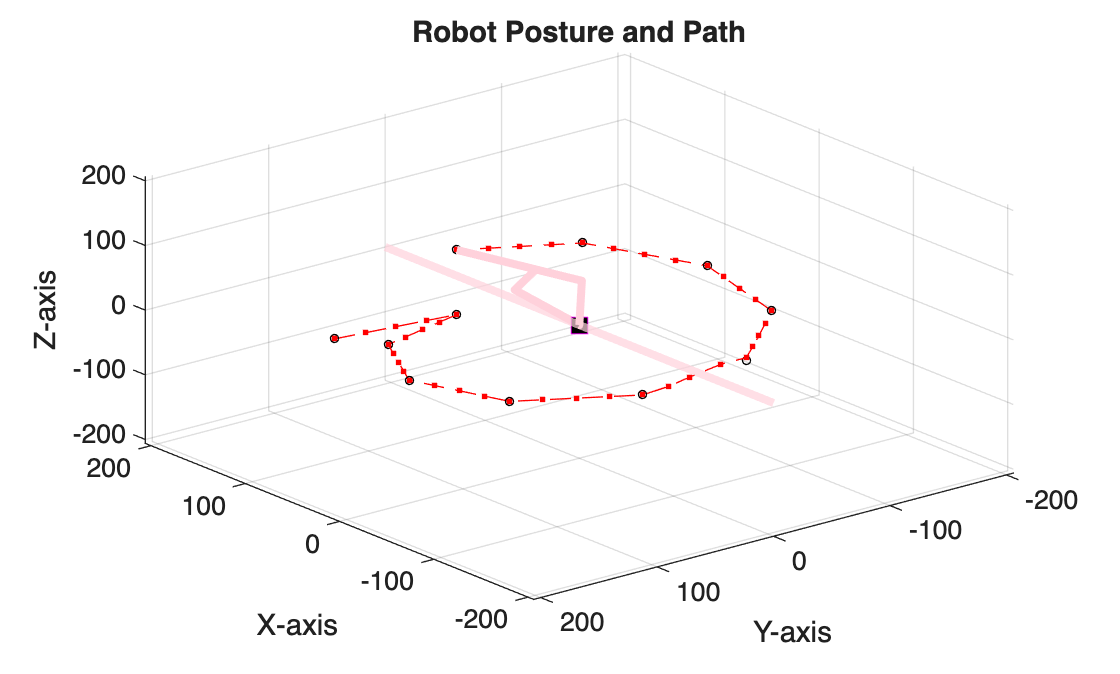

display_bounds = false;
display_postures = false;

if rad_check || solve_regardless
    f2 = figure;
    plot3(interest_nodes(1,:),interest_nodes(2,:),interest_nodes(3,:),'ko','MarkerSize',3)
    
    xlabel('X-axis');
    ylabel('Y-axis');
    zlabel('Z-axis');
    title('End Effector Path');
    legend off;
    grid on;
    view([231 37])
    axis([-max_L max_L -max_L max_L -max_L max_L]);
    ax = gca;
    ax.YAxisLocation = "origin";
    ax.XAxisLocation = "origin";
    hold on;
    plot3(O(1),O(2),O(3),'Marker','square','Color','m','MarkerSize',8,'MarkerFaceColor','k')
    yline(0,'Color',[1 0.82 0.86],'LineStyle','-','LineWidth',3)
    if display_bounds
        surf(rom_outX.*max_L,rom_outY.*max_L,rom_outZ.*max_L,'FaceAlpha',0.1,'EdgeColor','none','FaceColor','g')
        surf(rom_inX.*min_L,rom_inY.*min_L,rom_inZ.*min_L,'FaceAlpha',0.25,'EdgeColor','none','FaceColor','k')
    end
    r_post = animatedline('Color',[1 0.82 0.86],'LineStyle','-','LineWidth',3); % Arm 
    r_path = animatedline('Color','r','LineStyle','--','Marker','.'); % Solving Path
    l = 1;
    for i = 1:size(targetP,2)
        for j = 1:size(Joint_nodes{i},2)
            addpoints(r_post,[C_val{i}(1,j) A_val{i}(1,j) 0 B_val{i}(1,j) D_val{i}(1,j)],[C_val{i}(2,j) A_val{i}(2,j) 0 B_val{i}(2,j) D_val{i}(2,j)],[C_val{i}(3,j) A_val{i}(3,j) 0 B_val{i}(3,j) D_val{i}(3,j)]);
            if j == 1
                addpoints(r_path,D_val{i}(1,j),D_val{i}(2,j),D_val{i}(3,j));
            end
            tic
            while toc < 0.1
            end
            drawnow update
    
            if ~(sum(i == cumsum(resolutions+1)) > 0) || (j ~= size(Joint_nodes{i},2))
                clearpoints(r_post)
            end
        end
        if sum(i == [1 c_res(2:end - 1)]) == 1 && display_postures
            plot3([C_val{i}(1,end) A_val{i}(1,end) 0 B_val{i}(1,end) D_val{i}(1,end)],[C_val{i}(2,end) A_val{i}(2,end) 0 B_val{i}(2,end) D_val{i}(2,end)],[C_val{i}(3,end) A_val{i}(3,end) 0 B_val{i}(3,end) D_val{i}(3,end)],'--')
        end
    end
    hold off
    title('Robot Posture and Path');
end